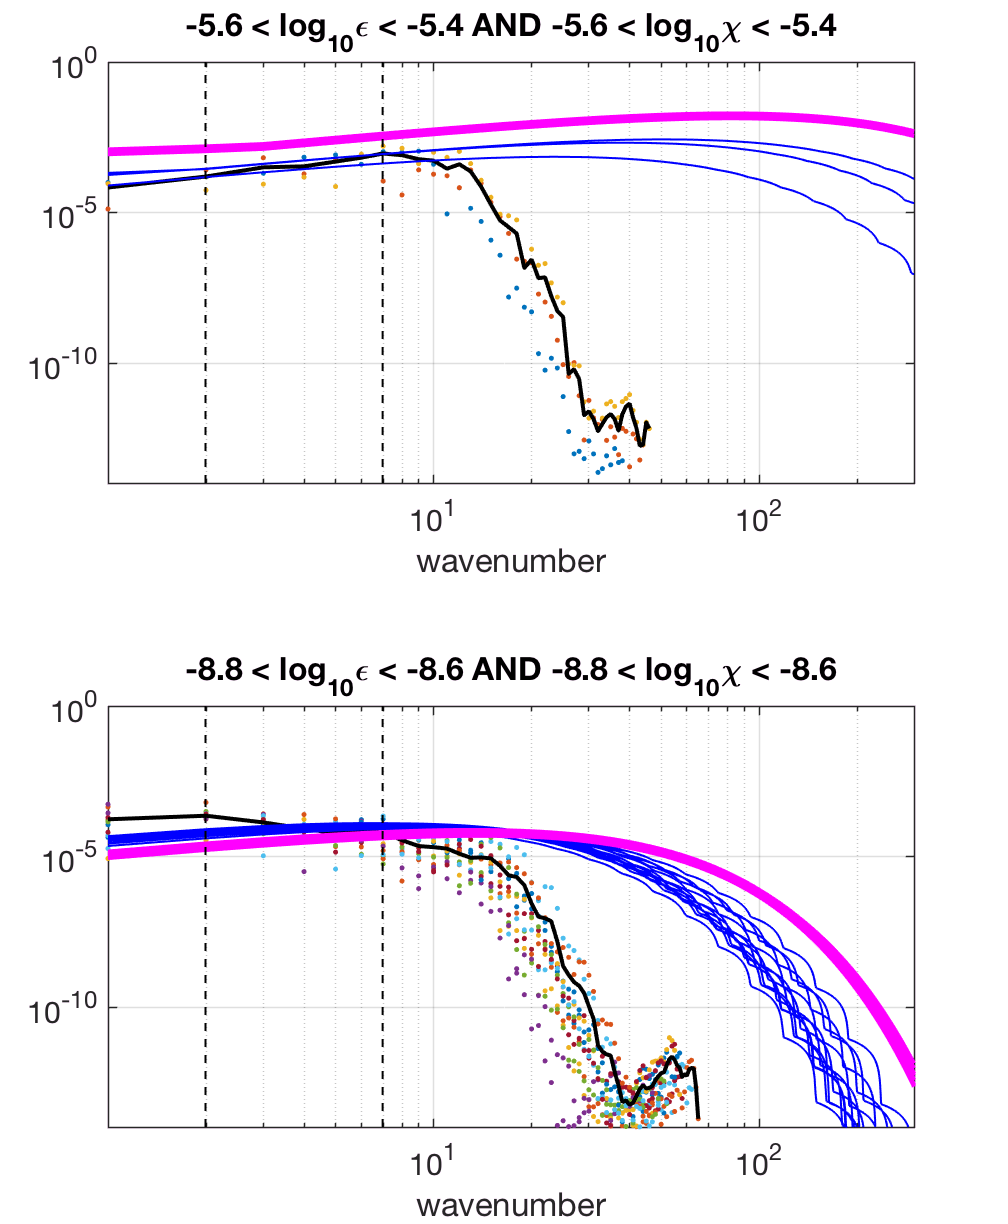

%~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
%
% PlotEQ14Spec.m
%
% dT/dt spectra are saved w/ GetAllSpecEQ14.m in file AllSpec_[dz].mat,
% where dz is the # of spectra to skip (too many to save all).
%
%-----------------
% 08/04/16 - A.Pickering
%~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
clear ; close all

addpath /Users/Andy/Cruises_Research/GenMatlabFunctions/
addpath /Users/Andy/Cruises_Research/mixingsoftware/general
% Load file with saved spectra
load('AllSpec_50.mat')
% Ratios of chipod method to chameleon 
clear chirat epsrat
chirat=AllSpec.all_chi_chi ./ AllSpec.all_chi_cham;
epsrat=AllSpec.all_eps_chi ./ AllSpec.all_eps_cham;

% (1) high eps,chi, and larger (negative) bias in chi
epsrange1=[-6.2 -6];
epsrange1=[-5.8 -5.6];
epsrange1=[-5.6 -5.4];
chirange1=epsrange1;
ig1=find(  log10(AllSpec.all_eps_cham)> epsrange1(1) & log10(AllSpec.all_eps_cham)< epsrange1(2) ...
    & log10(AllSpec.all_chi_cham)> chirange1(1) & log10(AllSpec.all_chi_cham)< chirange1(2) & log10(chirat)<-0.2) ;

% (2) low eps,chi, and smaller bias in chi
epsrange2=[-8.8 -8.6];
chirange2=epsrange2;
ig2=find(  log10(AllSpec.all_eps_cham)> epsrange2(1) & log10(AllSpec.all_eps_cham)< epsrange2(2) ...
    & log10(AllSpec.all_chi_cham)> chirange2(1) & log10(AllSpec.all_chi_cham)< chirange2(2) & log10(chirat)>-0.1 & log10(chirat)<0.1)  ;

%
figure(1);clf
agutwocolumn(1)
wysiwyg
set(gcf,'defaultaxesfontsize',15)

ax1=subplot(211);
loglog(AllSpec.ki,AllSpec.speci(ig1,:),'.')
hold on
loglog(AllSpec.ki,nanmean(AllSpec.speci(ig1,:)),'k','linewidth',2)
% Plot the (chi-pod method) fits
loglog(AllSpec.ki,(AllSpec.speci_fit(ig1,:)),'b','linewidth',1)

% Plot kraichnan spectra for this range too
nu=1e-6;
tdif=1.5e-7;
qq=7;
% eps=10^(nanmean(epsrange1))
% chi=10^(nanmean(chirange1))
for ii=1:length(ig1)
    eps=AllSpec.all_eps_cham(ig1(ii));
    chi=AllSpec.all_chi_cham(ig1(ii));
    
    kb = (((eps./(nu.^3)).^.25 )/2/pi).*sqrt(nu./tdif);
    [spec_vals]=kraichnan(nu,AllSpec.ki,kb,tdif,chi,qq);
    hcham=loglog(AllSpec.ki,spec_vals,'m','linewidth',2);
end

grid on
xlim([0 300])
ylim([1e-14 1e0])
freqline(2);
freqline(7);
title([num2str(epsrange1(1)) ' < log_{10}\epsilon < ' num2str(epsrange1(2)) ...
    ' AND ' num2str(chirange1(1)) ' < log_{10}\chi < ' num2str(chirange1(2))])
xlabel('wavenumber')

ax2=subplot(212);
loglog(AllSpec.ki,AllSpec.speci(ig2,:),'.')
hold on
loglog(AllSpec.ki,nanmean(AllSpec.speci(ig2,:)),'k','linewidth',2)
% Plot the (chi-pod method) fits
loglog(AllSpec.ki,(AllSpec.speci_fit(ig2,:)),'b','linewidth',1)

%eps=10^(nanmean(epsrange2))
%chi=10^(nanmean(chirange2))
for ii=1:length(ig2)
    eps=AllSpec.all_eps_cham(ig2(ii));
    chi=AllSpec.all_chi_cham(ig2(ii));
    
    kb = (((eps./(nu.^3)).^.25 )/2/pi).*sqrt(nu./tdif);
    [spec_vals]=kraichnan(nu,AllSpec.ki,kb,tdif,chi,qq);
    hcham=loglog(AllSpec.ki,spec_vals,'m','linewidth',2);
end

grid on
xlim([0 300])
ylim([1e-14 1e0])
freqline(2);
freqline(7);
title('log_{10}\epsilon > -8')
xlabel('wavenumber')
title([num2str(epsrange2(1)) ' < log_{10}\epsilon < ' num2str(epsrange2(2)) ...
    ' AND ' num2str(chirange2(1)) ' < log_{10}\chi < ' num2str(chirange2(2))])

linkaxes([ax1 ax2])
nanmean(log10(chirat(ig1)));
nanmean(log10(epsrat(ig1)));

nanmean(log10(chirat(ig2)));
nanmean(log10(epsrat(ig2)));

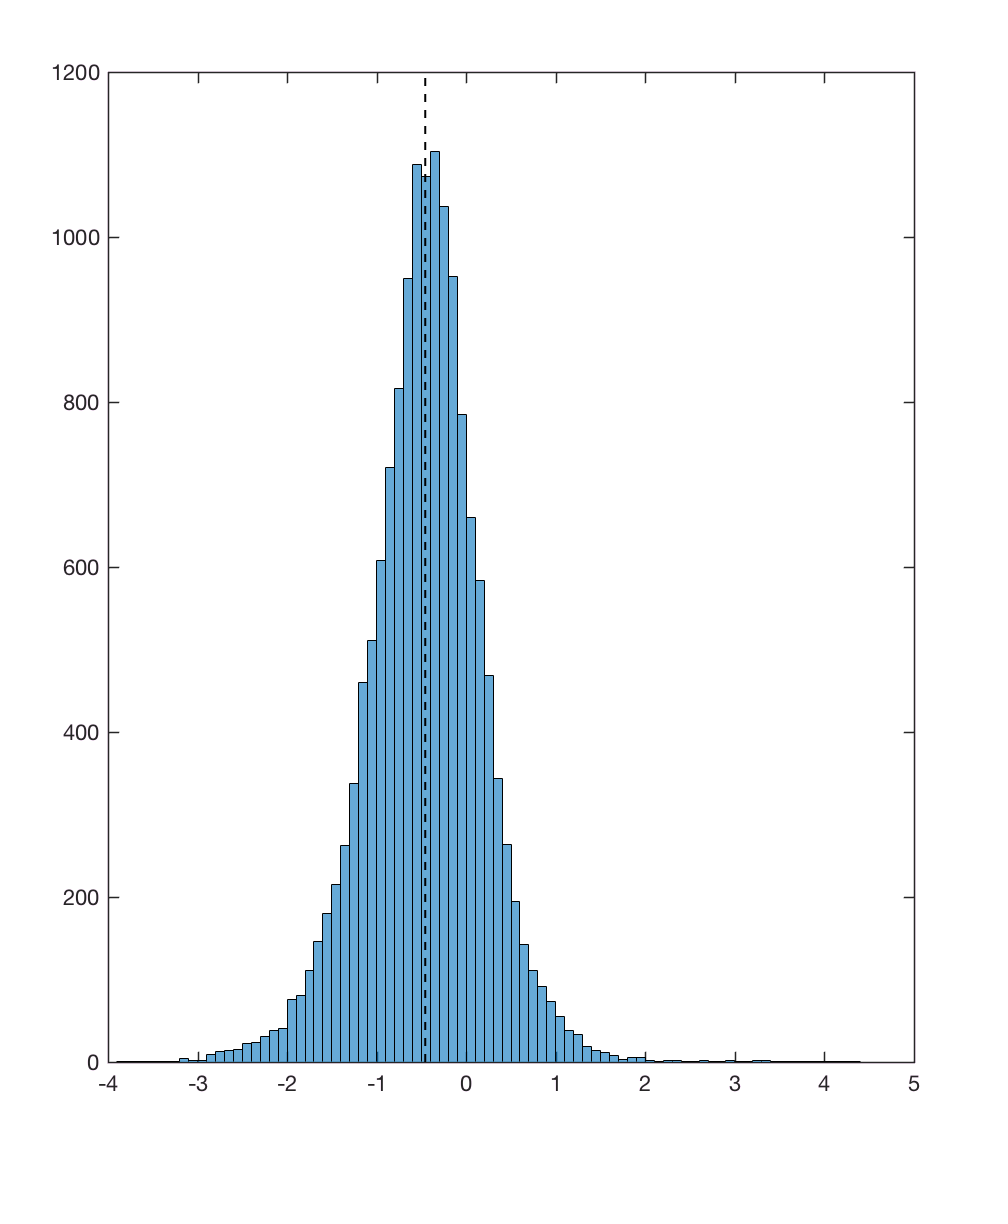

% ratio of chi_chi to chi_cham
chirat=AllSpec.all_chi_chi ./ AllSpec.all_chi_cham;
%%
figure(1);clf
agutwocolumn(0.5)
histogram(log10(chirat))
freqline(nanmean(log10(chirat)));
ig=find(log10(chirat)<-1.5);

figure(2);clf

subplot(211)
h1=histogram(log10(AllSpec.all_chi_cham),'Normalization','pdf');
hold on
h2=histogram(log10(AllSpec.all_chi_cham(ig)),h1.BinEdges,'Normalization','pdf');
xlabel('log_{10}\chi')
ylabel('pdf')
legend([h1 h2],'All','biased low')


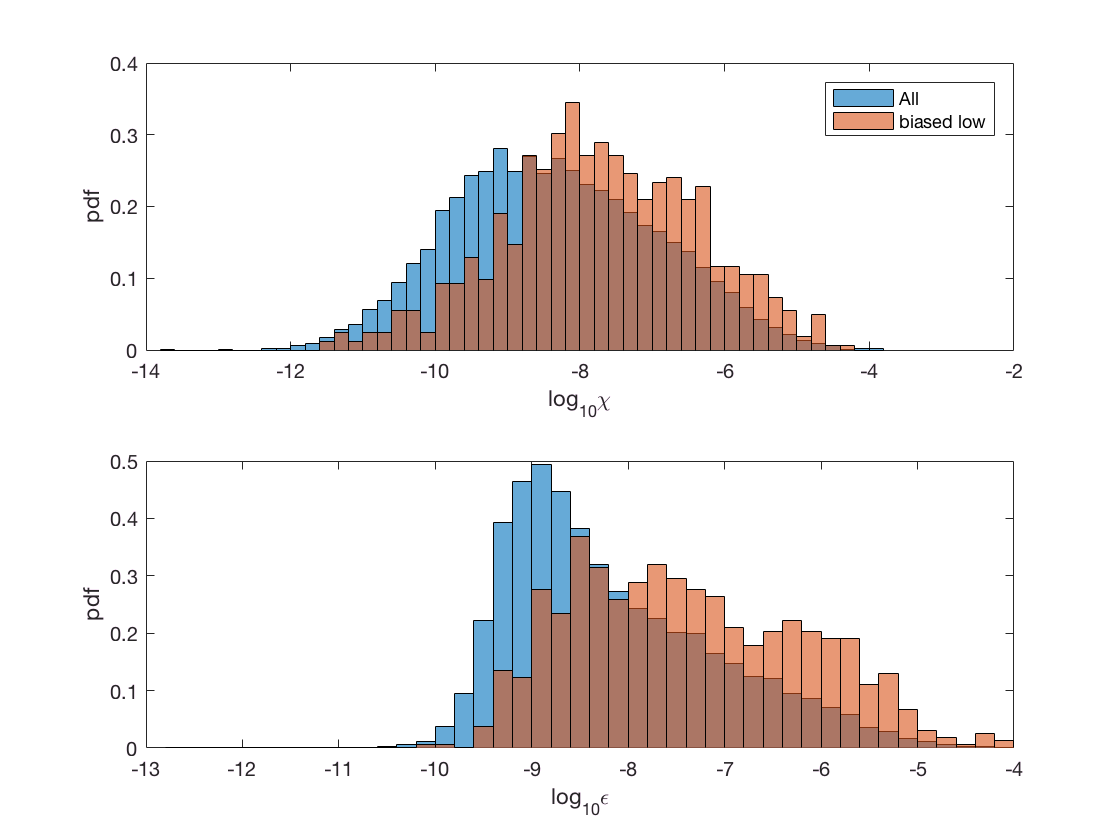

subplot(212)
h1=histogram(log10(AllSpec.all_eps_cham),'Normalization','pdf');
hold on
h2=histogram(log10(AllSpec.all_eps_cham(ig)),h1.BinEdges,'Normalization','pdf');
xlabel('log_{10}\epsilon')
ylabel('pdf')
ig1=find(log10(AllSpec.all_eps_cham)<-8);
ig2=find(log10(AllSpec.all_eps_cham)>-8);

figure(2);clf

subplot(211)
imagesc(log10(AllSpec.speci(ig1,:)))
colorbar
caxis([-11 -0])
xlim([0 60])
title('log_{10}\epsilon < -8')

subplot(212)
imagesc(log10(AllSpec.speci(ig2,:)))

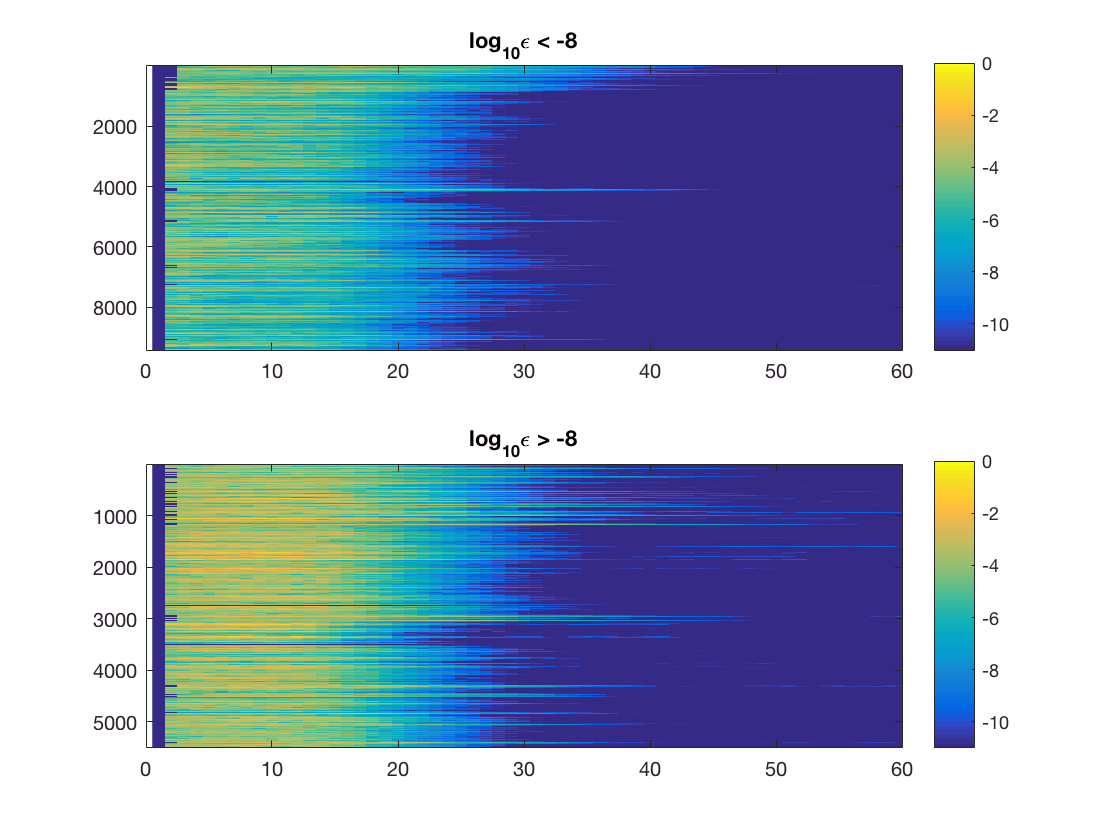

colorbar
caxis([-11 -0])
xlim([0 60])
title('log_{10}\epsilon > -8')